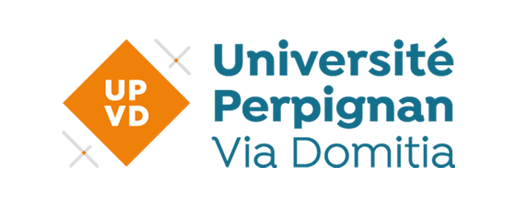

# **Commande optimale robustifiée LQG/LTR**

**Développement d'une commande LQG robustifiée par LTR **

**pour la régulation thermique d'une salle blanche**

**Majid GHORBANNEZHAD **

**2025 - 2026**

## Contexte

  « Une salle blanche (ou plus exactement salle propre selon la norme ISO 14644-1) est une pièce ou  une série de pièces où la concentration particulaire est maîtrisée afin de minimiser l'introduction, la  génération, la rétention de particules à l’intérieur, généralement dans un but spécifique industriel ou de  recherche scientifique. Les paramètres tels que la température, l'humidité et la pression relative sont  également maintenus à un niveau précis (définition selon la norme ISO 14644-1).  Les salles blanches sont utilisées dans les domaines sensibles aux contaminations  environnementales : la fabrication des dispositifs à semi-conducteurs, les biotechnologies et d'autres  domaines de la biologie, l’industrie agroalimentaire, généralement dans les salles de tranchage, la  construction d’engins spatiaux, la préparation des produits pharmaceutiques stériles, la construction  d’optique ou de micro-mécanismes, dans les hôpitaux pour les blocs opératoires ou de bactériologie. Ces  salles sont également utilisées dans le cadre de la recherche médicale pour la fabrication de radioéléments  par exemple.  Dans ces domaines, les objets et substances manipulés ont des tailles de l’ordre du micromètre ou  du nanomètre et les particules présentes dans l’air non purifié peuvent être bien plus grosses et se fixer  dessus. D’autre part, les expériences chimiques ou bactériologiques effectuées peuvent être dangereuses pour l’homme ou l’environnement. Ces travaux sont susceptibles d’être sensibles aux variations de  pression, de température, d’humidité ou à la présence de gaz, vapeurs chimiques ou matière radioactive  dans le cas de la fabrication d’isotopes. L’éclairage peut être également contrôlé pour les opérations  sensibles aux ultraviolets comme la photolithographie, aux infrarouges ou certaines fréquences du spectre  lumineux pour l'optique. Des exigences de ventilation nucléaire et de radioprotection peuvent également  s’imposer dans ces espaces. » (Source : Wikipédia, « salle blanche »).

## Description du système à piloter

  Nous intéressons ici à la régulation thermique d’une salle blanche équipée d’un système de  climatisation permettant de réchauffer ou refroidir la pièce (Figure 1). Une sonde de température permet  de mesurer la température de l’air ambiant $y_k$ dans la salle. La consigne de température $y_k^{\textrm{ref}}$ est fixée  sur l’interface utilisateur à 20°C pendant les horaires d’utilisation de la salle de 8h à 18h du lundi au  vendredi. Le reste du temps, lorsque la salle n’est pas utilisée la climatisation n’est pas maintenue pour  des raisons de coût économique. Le système de contrôle/commande détermine en temps réel la puissance  électrique $u_k$ devant être fourni par le système de chauffage/climatisation (en chaud ou en froid). 

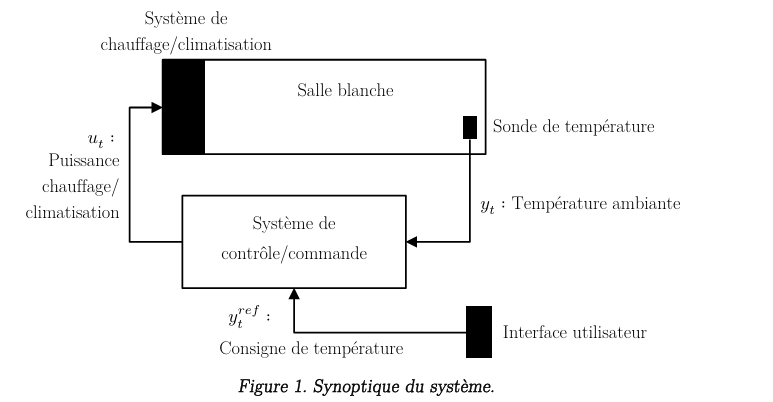

À partir d’essais expérimentaux, il a été possible de déterminer une fonction de transfert discrète  entre la puissance délivrée par le système de chauffage/climatisation et la température ambiante. 

 L’unité de temps est la minute. L’objectif est de développer un système de contrôle comprenant un  observateur d’état ainsi qu’un contrôleur par retour d’état possédant une action intégrale pour  supprimer les erreurs statiques. En raison de la présence d’un intégrateur dans le système qui fait  naturellement converger la sortie $y_t$vers la référence $y_t^{\textrm{ref}}$ , nous n’utiliserons pas de préfiltre  (⇒ $k_r$ = 0).

## Schéma de régulation 

 Le schéma de régulation à développer, présenté à la Figure 2 .

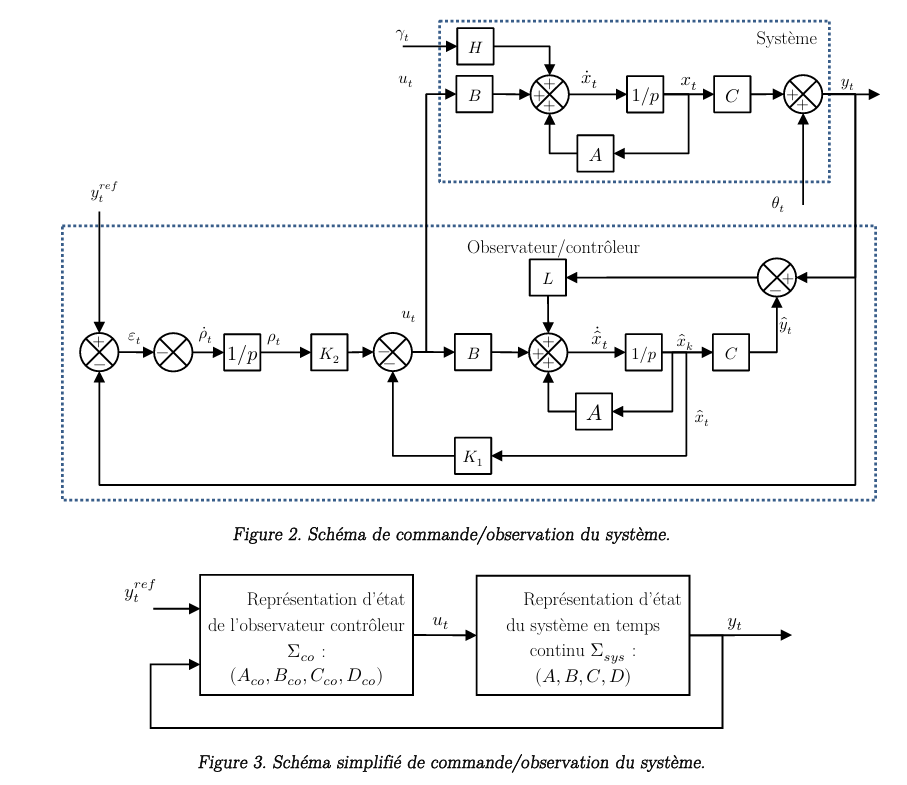

L’objectif est de développer un programme permettant de calculer le gain $L$ de l’observateur d’état  ainsi que les gains $k_1$ et $k_2$ du retour d’état. 

## 1. Définition et étude du système

% clc
% close all
% clear all

### Fonction de transfert du système

%Fonction de transfert
disp("======================================================================")

num = [1];
den = [100 20 1];
sys_c_tf = tf(num, den)  % Système continu

sys_c_tf =
 
          1
  ------------------
  100 s^2 + 20 s + 1
 
Continuous-time transfer function.
Model Properties


### Matrices de la représentation d’état du système 

disp("======================================================================")

[A,B,C,D] = tf2ss(num,den)

A =    -0.2000   -0.0100
    1.0000         0


B =      1
     0


C =          0    0.0100


D = 0

### Système sous forme de représentation d’état

disp("======================================================================")

sys_c_ss = ss(A,B,C,D)

sys_c_ss =
 
  A = 
          x1     x2
   x1   -0.2  -0.01
   x2      1      0
 
  B = 
       u1
   x1   1
   x2   0
 
  C = 
         x1    x2
   y1     0  0.01
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model Prop

###  Réponse indicielle

disp("======================================================================")

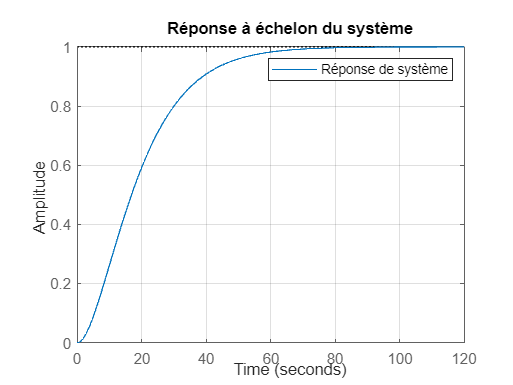

figure()
step(sys_c_ss)
title("Réponse à échelon du système")
legend("Réponse de système")
grid on


S1 = stepinfo(sys_c_ss,'SettlingTimeThreshold',0.05)

S1 = struct with fields:
         RiseTime: 33.5834
    TransientTime: 47.4387
     SettlingTime: 47.4387
      SettlingMin: 0.9019
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 119.2739


### INTERPRÉTATION DES RÉSULTATS :

#### 1. TEMPS DE RÉPONSE À 90% (SettlingTime = 47.44s)

 C'est le temps que met la réponse pour passer de 10 % à 90 % de sa valeur finale. Cela correspond à la rapidité du système à réagir au début.

- Temps relativement long indiquant un système lent

- Cohérent avec les constantes de temps élevées ($\tau =10\;s$)

#### 2. DÉPASSEMENT (Overshoot = 0%)

- La réponse ne présente aucun dépassement par rapport à la valeur finale.

- Le comportement du système est monotone et ne présente pas d’oscillations.

#### 3. GAIN STATIQUE 

- La valeur finale étant proche de 1, le gain statique est unitaire.

- L’erreur statique en régime permanent est négligeable. (Le système suit parfaitement la consigne en régime permanent)

#### 4. TEMPS DE MONTÉE (RiseTime = 33.58s)

- Le temps de montée relativement élevé traduit une dynamique lente caractéristique d’un système inertiel fortement amorti.

- Rapport RiseTime/SettlingTime ≈ 0.7, typique des systèmes amortis sans dépassement.

#### 5. COMPORTEMENT DYNAMIQUE

- La convergence vers la valeur finale est progressive et monotone, sans dépassement ni oscillation.

#### 6. PIC (Peak = 0.9999 à PeakTime = 119.27s)

- Le pic correspond à la valeur finale du système (absence de dépassement).

- Le temps de pic élevé confirme la dynamique lente du système, qui met environ 2 minutes à atteindre sa valeur finale.

#### CONCLUSION :

Ce système présente les caractéristiques d'un système du second ordre fortement amorti avec :

- Réponse lente mais stable

- Aucune oscillation

- Convergence monotone vers la valeur finale

- Temps d'établissement d'environ 47 secondes

- Comportement prévisible et bien amorti

###  Valeurs propres de la matrice A

disp("======================================================================")

Val_propre = eig(A)

Val_propre =   -0.1000 + 0.0000i
  -0.1000 - 0.0000i


### **Diagrame de bode**

disp("======================================================================")
figure()

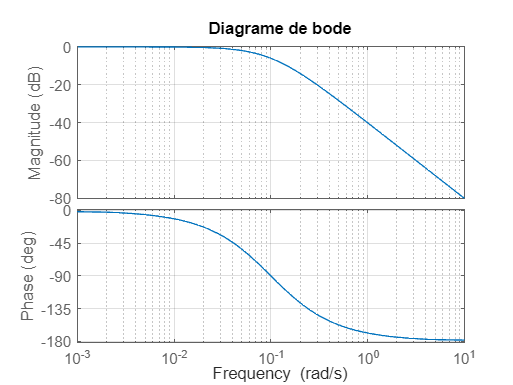

bode(sys_c_ss)
title("Diagrame de bode")
grid on


% Analyse de diagrame de Bode
% Calculs analytiques 
Gs_c = dcgain(sys_c_ss);                     % Gain statique
[mag_c, phase_c, w_c] = bode(sys_c_ss);      % Magnitude / Phase / fréquence

% Recherche précise de la fréquence de coupure à -3dB
mag_db = 20*log10(squeeze(mag_c));
gain_statique_db = 20*log10(Gs_c);
[~, idx_cut] = min(abs(mag_db - (gain_statique_db - 3)));  
Wc_c = w_c(idx_cut);                      % Fréquence de coupure précise

[num_c, den_c] = tfdata(sys_c_ss, 'v');
z = roots(num_c);                         % Zéros
p = roots(den_c);                         % Pôles
pente_asympt_dB = 20 * (length(z) - length(p));  % Pente asymptotique

% Affichage console 
fprintf('\n--- Analyse du diagramme de Bode ---\n');
fprintf('Gain statique (w = 0)       : %.4f\n', Gs_c);


--- Analyse du diagramme de Bode ---


fprintf('Fréquence de coupure (-3dB) : %.4f rad/s\n', Wc_c);

Gain statique (w = 0)       : 1.0000


fprintf('Pente asymptotique          : %.2f dB/décade\n', pente_asympt_dB);

Fréquence de coupure (-3dB) : 0.0625 rad/s


Pente asymptotique          : -40.00 dB/décade


Afin de pouvoir réaliser une commande LQG, le système doit être mis sous la forme : 

On considèrera donc ici : 

- $\Gamma =\Gamma^{\top } =\textrm{Var}\left(\gamma \right)=1\times I_2$  (un bruit de structure dont la variance est égale à 1 pour chaque état).

- 
$$H=\;1$$


- $\Theta =\Theta^{\top } =\textrm{Var}\left(\theta \right)=0,05$ (un bruit de mesure dont la variance est de 0,05)

disp("======================================================================")
H=1
gamma =  1 * eye(length(A)) %(un bruit de structure dont la variance est égale à 1 pour chaque état).
tta = 0.05 %(un bruit de mesure dont la variance est de 0,05)

## 2. Observateur d’état optimal

L’objectif de cette partie est de calculer le gain $L$ de l’estimateur d’état optimal par la méthode  LQG. 

### Stabilisabilité et Détectabilité

- **Stabilisabilité de **$\left({A,\textrm{H𝛤}}^{\frac{1}{2}} \right)$  

disp("======================================================================")

Ctro = ctrb(A,H*gamma^(1/2))

H = 1

Ctro_rang = rank(Ctro)

gamma =      1     0
     0     1


if (Ctro_rang == size(A,1))

tta = 0.0500

    fprintf('Paire (A,H*Gamma^1/2) contrôlable.\n')
else
    fprintf("Paire (A,H*Gamma^1/2) n'est pas contrôlable.\n")
end

- **Détectabilité de **$\left(A,C\right)$  

disp("======================================================================")

Ob = obsv(A,C)

Ctro =     1.0000         0   -0.2000   -0.0100
         0    1.0000    1.0000         0


Ob_rang = rank(Ob)

Ctro_rang = 2

if (Ob_rang == size(A,1))
    fprintf('Paire (A,C) observable.\n')
else
    fprintf("Paire (A,C) n'est pas observable.\n")
end

Paire (A,H*Gamma^1/2) contrôlable.


### Gain de l'observateur

disp("======================================================================")

Ob =          0    0.0100
    0.0100         0


q = H*gamma*H'

Ob_rang = 2

[M, L ,~] = icare(A',C',q,tta,[],[]) 
L = L'


Paire (A,C) observable.


### Matrice d’évolution BF

On s'intéresse à calculer $A_{OBF} =A-LC$, c’est-à-dire la matrice d’évolution en boucle fermée de l’observateur.

disp("======================================================================")

Aobf = A -L*C
VPAobf = eig(Aobf)

q =      1     0
     0     1


## 3. Commande par retour d’état optimale

L’objectif de cette partie est de calculer le gain k d’une commande optimale par la méthode LQG.  Afin d’éviter les erreurs statiques de suivi de consigne, on ajoute dans le système un intégrateur  sous la forme : 


$${\dot{\rho} }_t =y_t -y^{\textrm{ref}}$$


ALors, on augmente le système en ajoutant l’état supplémentaire, en considérant le vecteur d’état augmenté : 


$$x_{a,t} =\left\lbrack \begin{array}{c}
x_t \\
\rho_t 
\end{array}\right\rbrack$$


Pour cela, nous définisson les quatre matrices $A_a$, $B_a$, $C_a$ et $D_a$ de la représentation d’état du système augmenté.

###  Système augmenté 

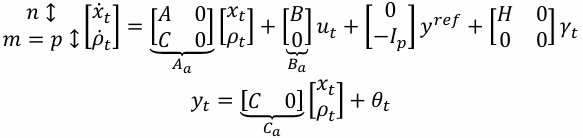

disp("======================================================================")

M =     2.1853    4.3775
    4.3775   69.8389


L =     0.8755   13.9678


Aa = [A zeros(2,1);

L =     0.8755
   13.9678


    C zeros(1,1)]
Ba1 = [B;0]
Ba2 = [zeros(2,1);-eye(1,1)]
Ca =  [C 0]

Da = [0]

Aobf =    -0.2000   -0.0188
    1.0000   -0.1397


VPAobf =   -0.1698 + 0.1336i
  -0.1698 - 0.1336i


VPAa= eig(Aa)

On souhaite maintenant développer une commande optimale qui minimise le critère :

En considérant :

On obtient le critère sous forme classique :

Pour la suite on considère :

-    (pondération sur la sortie) ;

- $Q_{\rho } =1$ (pondération de l’intégrateur) ;

- $R=0,01$ (pondération de la commande).

disp("======================================================================")

Q = 10
Qp = 1
R = 0.01

Aa =    -0.2000   -0.0100         0
    1.0000         0         0
         0    0.0100         0


Ba1 =      1
     0
     0


Qa = [C'*Q*C zeros(2,1);

Ba2 =      0
     0
    -1


    zeros(1,2) Qp]

Ca =          0    0.0100         0


### Stabilisabilité et Détectabilité

- **Stabilisabilité de **$\left(A_a ,B_a \right)$ 

disp("======================================================================")

Da = 0

CtrC = ctrb(Aa,Ba1)
c1 = rank(CtrC)

VPAa =    0.0000 + 0.0000i
  -0.1000 + 0.0000i
  -0.1000 - 0.0000i


if (c1 == size(Aa,1))
    fprintf('Paire (Aa,Ba) contrôlable.\n')
else
    fprintf("Paire (Aa,Ba) n'est pas contrôlable.\n")
end


- **Détectabilité de **$\left(A,Q^{\frac{1}{2}} C\right)$  

disp("======================================================================")

ObsC = obsv(A,Q^(1/2)*C)

Q = 10

c2 = rank(ObsC)

Qp = 1

if (c2 == size(A,1))

R = 0.0100

    fprintf('Paire (A,Q^(1/2)*C) observable.\n')
else
    fprintf("Paire (A,Q^(1/2)*C) n'est pas observable.\n")

Qa =          0         0         0
         0    0.0010         0
         0         0    1.0000


end


### Gain de commande

disp("======================================================================")

CtrC =     1.0000   -0.2000    0.0300
         0    1.0000   -0.2000
         0         0    0.0100


[P, K ,~] = icare(Aa,Ba1,Qa,R,[],[])

c1 = 3


K1 = K(:,1:2)
K2= K(:,3)

Paire (Aa,Ba) contrôlable.


### Matrice d’évolution BF

On  calcule $A_{\textrm{CB}F} =A_a -B_a K$ la matrice d’évolution en boucle fermée de la commande.

disp("======================================================================")

Acbf = Aa - Ba1*K

ObsC =          0    0.0316
    0.0316         0


VPAcbf = eig(Acbf)

c2 = 2

## 4. Synthèse observateur/contrôleur

L’objectif de cette partie est de déterminer les fonctions de transfert de la boucle fermée, de la  boucle ouverte et de la fonction de sensibilité afin d’étudier la réponse du système et d’analyser les  marges de robustesses. Pour cela, on va calculer les différents transferts. 

### Représentation d'état observateur/contrôleur

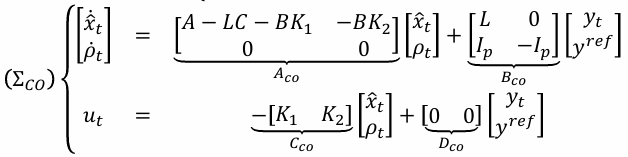

disp("======================================================================")
Aco = [A-L*C-B*K1, -B*K2;
    zeros(1,2), zeros(1)]
Bco = [L, zeros(2,1);
    eye(1,1), -eye(1,1)]
Cco = [-K1, -K2]

Paire (A,Q^(1/2)*C) observable.


Dco =[0,0]
sys_co = ss(Aco,Bco,Cco,Dco)

### Représentation d'état BO

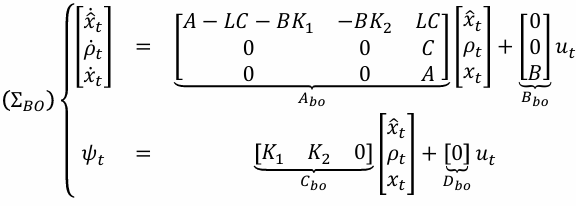

disp("======================================================================")

P =     0.0087    0.0055    0.1000
    0.0055    0.0050    0.1068
    0.1000    0.1068    5.6004


K =     0.8677    0.5500   10.0000


Abo = [A - L*C - B*K1, -B*K2, L*C;
       zeros(1,2), zeros(1,1), C;

K1 =     0.8677    0.5500


       zeros(2,2), zeros(2,1), A];

K2 = 10.0000

Bbo = [zeros(2,1); zeros(1,1); B];
Cbo = [K1, K2 zeros(1,2)];
Dbo = [0];

sys_bo = ss(Abo,Bbo,Cbo,Dbo)

Acbf =    -1.0677   -0.5600  -10.0000
    1.0000         0         0
         0    0.0100         0


### Représentation d'état BF

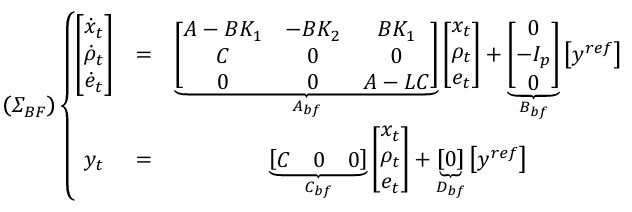

disp("======================================================================")

VPAcbf =   -0.3810 + 0.4265i
  -0.3810 - 0.4265i
  -0.3058 + 0.0000i


Abf = [A - B*K1, -B*K2, B*K1;
       C, zeros(1, 1), zeros(1, 2);
       zeros(2, 2), zeros(2, 1), A-L*C];
Bbf = [zeros(2, 1); -eye(1, 1); zeros(2, 1)];
Cbf = [C zeros(1, 1) zeros(1, 2)];

Dbf = [0];
sys_bf = ss(Abf,Bbf,Cbf,Dbf)


Aco =    -1.0677   -0.5688  -10.0000
    1.0000   -0.1397         0
         0         0         0


### Représentation d'état de fonction de sensibilité

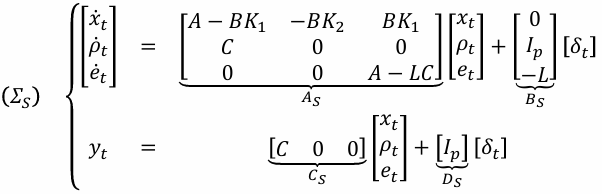

disp("======================================================================")
As = [A - B*K1, -B*K2, B*K1;

Bco =     0.8755         0
   13.9678         0
    1.0000   -1.0000


Cco =    -0.8677   -0.5500  -10.0000


       C, zeros(1, 1), zeros(1, 2);

Dco =      0     0


       zeros(2, 2), zeros(2, 1), A-L*C];

sys_co =
 
  A = 
            x1       x2       x3
   x1   -1.068  -0.5688      -10
   x2        1  -0.1397        0
   x3        0        0        0
 
  B = 
           u1      u2
   x1  0.8755       0
   x2   13.97       0
   x3       1      -1
 
  C = 
            x1       x2       x3
   y1  -0.8677    -0.55      -10
 
  D = 
       u1  u2
   y1   0   0
 
Continuous-time state-space model.


Bs = [zeros(2, 1); eye(1, 1); -L];
Cs = [C zeros(1, 1) zeros(1, 2)];
Ds = [eye(1, 1)];

sys_s = ss(As,Bs,Cs,Ds)

On souhaite comparer les performances de l’observateur contrôleur (LQG) au système bouclé sans observateur (LQ). 

### Représentation d'état BO LQ

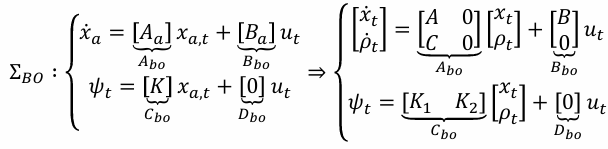

disp("======================================================================")
AboLQ = [A, zeros(2,1);
    C, zeros(1,1)];
BboLQ = [B; 0];
CboLQ = [K1, K2];
DboLQ = [0];

sys_bo =
 
  A = 
             x1        x2        x3        x4        x5
   x1    -1.068   -0.5688       -10         0  0.008755
   x2         1   -0.1397         0         0    0.1397
   x3         0         0         0         0      0.01
   x4         0         0         0      -0.2     -0.01
   x5         0         0         0         1         0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
   x5   0
 
  C = 
           x1      x2      x3      x4      x5
   y1  0.8677    0.55      10       0       0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


sys_bo_LQ = ss(AboLQ,BboLQ,CboLQ,DboLQ)

### Représentation d'état de fonction de sensibilité LQ

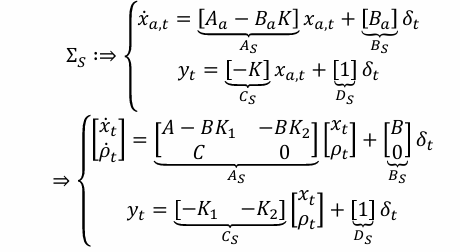

disp("======================================================================")

AsLQ = [A-B*K1, -B*K2;
    C, zeros(1,1)];
BsLQ = [B; 0];
CsLQ = [-K1, -K2];
DsLQ = [1];
sys_s_LQ = ss(AsLQ,BsLQ,CsLQ,DsLQ)

### Représentation d'état BF LQ

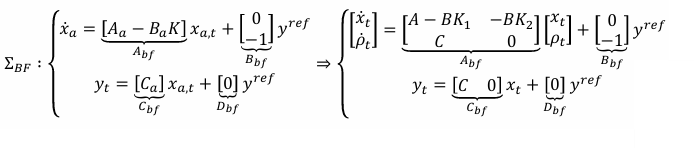

disp("======================================================================")

sys_bf =
 
  A = 
             x1        x2        x3        x4        x5
   x1    -1.068     -0.56       -10    0.8677      0.55
   x2         1         0         0         0         0
   x3         0      0.01         0         0         0
   x4         0         0         0      -0.2  -0.01875
   x5         0         0         0         1   -0.1397
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
   x4   0
   x5   0
 
  C = 
         x1    x2    x3    x4    x5
   y1     0  0.01     0     0     0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


AbfLQ = [A-B*K1, -B*K2;
    C, zeros(1,1)];
BbfLQ = [zeros(2,1); -1];
CbfLQ = [C, 0];

DbfLQ = [0];
sys_bf_LQ = ss(AbfLQ,BbfLQ,CbfLQ,DbfLQ)

On souhaite maintenant comparer et analyser les réponses temporelles et fréquentielles des deux  bouclages (avec et sans observateur).

### Réponse indicielle des boucles fermées

disp("======================================================================")
figure
step(sys_bf, 'b', sys_bf_LQ, 'r--')

sys_s =
 
  A = 
             x1        x2        x3        x4        x5
   x1    -1.068     -0.56       -10    0.8677      0.55
   x2         1         0         0         0         0
   x3         0      0.01         0         0         0
   x4         0         0         0      -0.2  -0.01875
   x5         0         0         0         1   -0.1397
 
  B = 
            u1
   x1        0
   x2        0
   x3        1
   x4  -0.8755
   x5   -13.97
 
  C = 
         x1    x2    x3    x4    x5
   y1     0  0.01     0     0     0
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.


grid on
title("Réponse indicielle du système en Boucle Fermée")
legend("LQG", "LQ")


Sbf_LQG = stepinfo(sys_bf,'SettlingTimeThreshold',0.05)
Sbf_LQ = stepinfo(sys_bf_LQ,'SettlingTimeThreshold',0.05)


### Diagramme du bode des boucles fermées

disp("======================================================================")
figure
bode(sys_bf, 'b', sys_bf_LQ, 'r--')

sys_bo_LQ =
 
  A = 
          x1     x2     x3
   x1   -0.2  -0.01      0
   x2      1      0      0
   x3      0   0.01      0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
           x1      x2      x3
   y1  0.8677    0.55      10
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


grid on
title("Diagramme du bode du système en Boucle Fermée")
legend("LQG", "LQ")

### Diagramme du bode des boucles ouvertes

disp("======================================================================")
figure
bode(sys_bo, 'b', sys_bo_LQ, 'r--')
grid on
title("Diagramme du bode du système en Boucle ouverte")
legend("LQG", "LQ")

sys_s_LQ =
 
  A = 
           x1      x2      x3
   x1  -1.068   -0.56     -10
   x2       1       0       0
   x3       0    0.01       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
            x1       x2       x3
   y1  -0.8677    -0.55      -10
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.


disp("======================================================================")
%détermination des marges de gain et de phase
SLQG = allmargin(sys_bo);

GmLQG_dB = 20 * log10(SLQG.GainMargin);
SLQ = allmargin(sys_bo_LQ);
GmLQ_dB = 20 * log10(SLQ.GainMargin);

disp("===== détermination des marges de gain et de phase =====");


sys_bf_LQ =
 
  A = 
           x1      x2      x3
   x1  -1.068   -0.56     -10
   x2       1       0       0
   x3       0    0.01       0
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
 
  C = 
         x1    x2    x3
   y1     0  0.01     0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


fprintf("Système LQG :\n");
fprintf("Marge de gain 'LQG' : Gm = %.4f dB à %.4f rad/min\n", GmLQG_dB, SLQG.GMFrequency);
fprintf("Marge de phase 'LQG' : Pm = %.4f deg à %.4f rad/min\n", SLQG.PhaseMargin, SLQG.PMFrequency);


fprintf("\nSystème LQ :\n");
fprintf("Marge de gain 'LQ' : Gm = %.4f dB à %.4f rad/min\n", GmLQ_dB, SLQ.GMFrequency); % infini
fprintf("Marge de phase 'LQ' : Pm = %.4f deg à %.4f rad/min\n", SLQ.PhaseMargin, SLQ.PMFrequency);

###  Diagramme de Bode des fonctions de sensibilité 

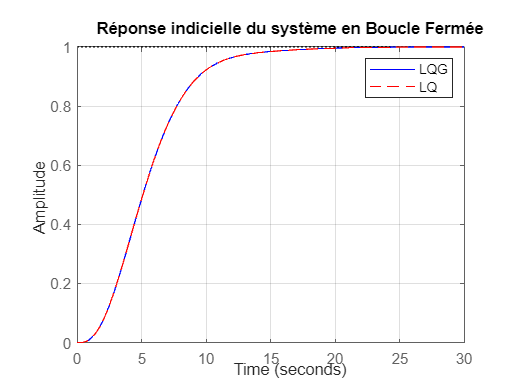

disp("======================================================================")

figure
bode(sys_s, 'b', sys_s_LQ, 'r--')

Sbf_LQG = struct with fields:
         RiseTime: 7.1487
    TransientTime: 11.0903
     SettlingTime: 11.0903
      SettlingMin: 0.9042
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 32.9853


grid on

Sbf_LQ = struct with fields:
         RiseTime: 7.1487
    TransientTime: 11.0903
     SettlingTime: 11.0903
      SettlingMin: 0.9042
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 32.9853


title("Diagramme du bode de la fonction de sensibilité")
legend("LQG", "LQ")


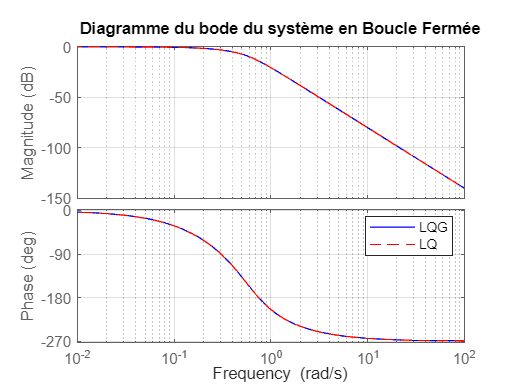

% Calcul de la marge de module 
MmLQG = 1/max(bode(sys_s));
MmLQ = 1/max(bode(sys_s_LQ));
disp("===== détermination des marges de Module =====");
fprintf("Marge du modile du Système LQG :\n");

fprintf('Marge de Module :Mm (LQG) =  %.4f', MmLQG);


fprintf("Marge du modile du Système LQ :\n");
fprintf('Marge de Module :Mm (LQ) =  %.2f', MmLQ);

%Nyquiste (Facultatif)

## 5. Procédure LTR

Cette partie vise à renforcer la robustesse de l’asservissement par LQG grâce à la procédure de recouvrement asymptotique LTR. On souhaite que les fonctions de transfert en boucle ouverte et la sensabilité du système bouclé avec observateur tendent, notamment en basse fréquence, vers celles obtenues avec une commande LQ sans observateur.

On cherche $\Gamma$ tel que: $\Gamma$ = ${\textrm{𝛤}}_0$ +${\textrm{qBB}}^T$ avec ${\textrm{𝛤}}_0 =I_2$ (valeur utilisée précédemment) et souhaite choisir une valeur de q qui permette d’améliorer la robustesse.

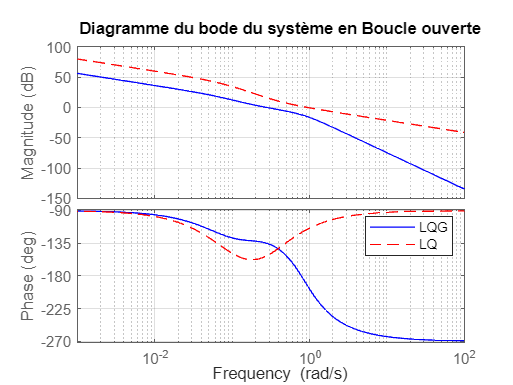

gamma0 = 1 * eye(length(A)); % = gamma utilisée précédemment (Partie 1)

qu = 10^9;

gamma = gamma0 + qu*B*B'
disp("===== Détermination 𝛤 tel que 𝛤 = 𝛤0 + 𝑞BB' en ajustant q =====");
disp(" Les contraintes à respecter sont : ");
disp(" 𝑀𝑚>0.95 ");
disp(" 𝑀𝐺>35 dB ");
disp(" 𝑀𝜑>60° ");
fprintf("\n Valeur ajusté pour q => q = %d \n", qu);

===== détermination des marges de gain et de phase =====


fprintf("\n Nouveau 𝛤 après ajustement :\n");
disp(gamma);

Système LQG :


Reprendre les démarches précédents pour nouveau $\Gamma$ en ajustant q  qui permette d’améliorer la robustesse  du système afin d’atteindre les performances suivantes proche de celles du système bouclé sans observateur : 

- 
$$M_m >0,95$$


- 
$$M_G >35\;\textrm{dB}$$


- 
$$M_{\varphi } >{60}^{\circ }$$


Marge de gain 'LQG' : Gm = 12.0294 dB à 0.7826 rad/min


disp("======================================================================")

Marge de phase 'LQG' : Pm = 44.9829 deg à 0.2782 rad/min


disp("===== Après avoir ajusté q =====");
q = H*gamma*H'


Système LQ :


[M, L ,~] = icare(A',C',q,tta,[],[]) 

Marge de gain 'LQ' : Gm =  dB à  rad/min


L = L'

Marge de phase 'LQ' : Pm = 64.4443 deg à 0.9436 rad/min



disp("======================================================================")

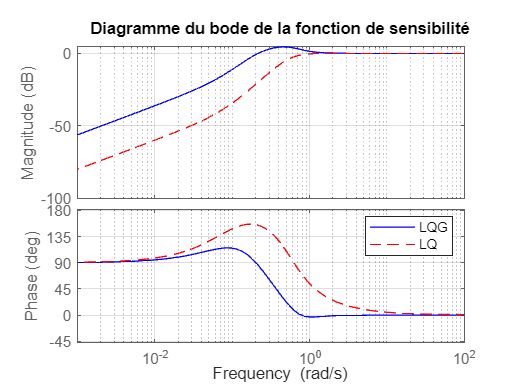

Abo = [A - L*C - B*K1, -B*K2, L*C;
       zeros(1,2), zeros(1,1), C;
       zeros(2,2), zeros(2,1), A]
Bbo = [zeros(2,1); zeros(1,1); B]
Cbo = [K1, K2 zeros(1,2)]

Dbo = [0]
sys_bo = ss(Abo,Bbo,Cbo,Dbo)

disp("======================================================================")
Abf = [A - B*K1, -B*K2, B*K1;

===== détermination des marges de Module =====


       C, zeros(1, 1), zeros(1, 2);

Marge du modile du Système LQG :


       zeros(2, 2), zeros(2, 1), A-L*C]

Marge de Module :Mm (LQG) =  0.6044

Bbf = [zeros(2, 1); -eye(1, 1); zeros(2, 1)]
Cbf = [C zeros(1, 1) zeros(1, 2)]

Marge du modile du Système LQ :


Dbf = [0]

Marge de Module :Mm (LQ) =  1.00

sys_bf = ss(Abf,Bbf,Cbf,Dbf)

disp("======================================================================")
As = [A - B*K1, -B*K2, B*K1;
       C, zeros(1, 1), zeros(1, 2);
       zeros(2, 2), zeros(2, 1), A-L*C]
Bs = [zeros(2, 1); eye(1, 1); -L]
Cs = [C zeros(1, 1) zeros(1, 2)]

gamma = 1.0e+09 *

    1.0000         0
         0    0.0000


Ds = [eye(1, 1)]

===== Détermination 𝛤 tel que 𝛤 = 𝛤0 + 𝑞BB' en ajustant q =====


sys_s = ss(As,Bs,Cs,Ds)

 Les contraintes à respecter sont : 


 𝑀𝑚>0.95 


disp("======================================================================")

 𝑀𝐺>35 dB 


AboLQ = [A, zeros(2,1);

 𝑀𝜑>60° 


    C, zeros(1,1)];


 Valeur ajusté pour q => q = 1000000000 


BboLQ = [B; 0];


 Nouveau 𝛤 après ajustement :


CboLQ = [K1, K2];

   1.0e+09 *

    1.0000         0
         0    0.0000



DboLQ = [0];
sys_bo_LQ = ss(AboLQ,BboLQ,CboLQ,DboLQ)

disp("======================================================================")

AsLQ = [A-B*K1, -B*K2;

===== Après avoir ajusté q =====


    C, zeros(1,1)];

q = 1.0e+09 *

    1.0000         0
         0    0.0000


BsLQ = [B; 0];

M = 1.0e+07 *

    3.7324    0.0702
    0.0702    0.0026


L = 1.0e+05 *

    1.4036    0.0530


CsLQ = [-K1, -K2];

L = 1.0e+05 *

    1.4036
    0.0530


DsLQ = [1];
sys_s_LQ = ss(AsLQ,BsLQ,CsLQ,DsLQ)


disp("======================================================================")
AbfLQ = [A-B*K1, -B*K2;
    C, zeros(1,1)];

Abo = 1.0e+03 *

   -0.0011   -1.4042   -0.0100         0    1.4036
    0.0010   -0.0530         0         0    0.0530
         0         0         0         0    0.0000
         0         0         0   -0.0002   -0.0000
         0         0         0    0.0010         0


Bbo =      0
     0
     0
     1
     0


BbfLQ = [zeros(2,1); -1];

Cbo =     0.8677    0.5500   10.0000         0         0


CbfLQ = [C, 0];

Dbo = 0

DbfLQ = [0];

sys_bo =
 
  A = 
           x1      x2      x3      x4      x5
   x1  -1.068   -1404     -10       0    1404
   x2       1  -52.98       0       0   52.98
   x3       0       0       0       0    0.01
   x4       0       0       0    -0.2   -0.01
   x5       0       0       0       1       0
 
  B = 
       u1
   x1   0
   x2   0
   x3   0
   x4   1
   x5   0
 
  C = 
           x1      x2      x3      x4      x5
   y1  0.8677    0.55      10       0       0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


sys_bf_LQ = ss(AbfLQ,BbfLQ,CbfLQ,DbfLQ)


disp("======================================================================")
%réponse indicielle du système en boucles fermée
figure
step(sys_bf, 'b', sys_bf_LQ, 'r--')

Abf = 1.0e+03 *

   -0.0011   -0.0006   -0.0100    0.0009    0.0006
    0.0010         0         0         0         0
         0    0.0000         0         0         0
         0         0         0   -0.0002   -1.4036
         0         0         0    0.0010   -0.0530


Bbf =      0
     0
    -1
     0
     0


grid on

Cbf =          0    0.0100         0         0         0


title("Réponse indicielle du système en Boucle Fermée (Nouveau gamma)")

Dbf = 0

legend("LQG", "LQ")

sys_bf =
 
  A = 
           x1      x2      x3      x4      x5
   x1  -1.068   -0.56     -10  0.8677    0.55
   x2       1       0       0       0       0
   x3       0    0.01       0       0       0
   x4       0       0       0    -0.2   -1404
   x5       0       0       0       1  -52.98
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
   x4   0
   x5   0
 
  C = 
         x1    x2    x3    x4    x5
   y1     0  0.01     0     0     0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



Sbf_LQG = stepinfo(sys_bf,'SettlingTimeThreshold',0.05)

Sbf_LQ = stepinfo(sys_bf_LQ,'SettlingTimeThreshold',0.05)

disp("======================================================================")
% Diagramme du bode du système en boucle fermée

As = 1.0e+03 *

   -0.0011   -0.0006   -0.0100    0.0009    0.0006
    0.0010         0         0         0         0
         0    0.0000         0         0         0
         0         0         0   -0.0002   -1.4036
         0         0         0    0.0010   -0.0530


Bs = 1.0e+05 *

         0
         0
    0.0000
   -1.4036
   -0.0530


figure

Cs =          0    0.0100         0         0         0


bode(sys_bf, 'b', sys_bf_LQ, 'r--')

Ds = 1

grid on

sys_s =
 
  A = 
           x1      x2      x3      x4      x5
   x1  -1.068   -0.56     -10  0.8677    0.55
   x2       1       0       0       0       0
   x3       0    0.01       0       0       0
   x4       0       0       0    -0.2   -1404
   x5       0       0       0       1  -52.98
 
  B = 
               u1
   x1           0
   x2           0
   x3           1
   x4  -1.404e+05
   x5       -5298
 
  C = 
         x1    x2    x3    x4    x5
   y1     0  0.01     0     0     0
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.


title("Diagramme du bode du système en Boucle Fermée (Nouveau gamma)")
legend("LQG", "LQ")


disp("======================================================================")
%Diagramme du bode du système en boucle ouverte
figure
bode(sys_bo, 'b', sys_bo_LQ, 'r--')
grid on

sys_bo_LQ =
 
  A = 
          x1     x2     x3
   x1   -0.2  -0.01      0
   x2      1      0      0
   x3      0   0.01      0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
           x1      x2      x3
   y1  0.8677    0.55      10
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


title("Diagramme du bode du système en Boucle ouverte (Nouveau gamma)")
legend("LQG", "LQ")


disp("======================================================================")
%détermination des marges de gain et de phase
SLQG = allmargin(sys_bo);
GmLQG_dB = 20 * log10(SLQG.GainMargin);
SLQ = allmargin(sys_bo_LQ);

sys_s_LQ =
 
  A = 
           x1      x2      x3
   x1  -1.068   -0.56     -10
   x2       1       0       0
   x3       0    0.01       0
 
  B = 
       u1
   x1   1
   x2   0
   x3   0
 
  C = 
            x1       x2       x3
   y1  -0.8677    -0.55      -10
 
  D = 
       u1
   y1   1
 
Continuous-time state-space model.


GmLQ_dB = 20 * log10(SLQ.GainMargin);


disp("===== détermination des marges de gain et de phase =====");

fprintf("Système LQG :\n");
fprintf("Marge de gain 'LQG' : Gm = %.4f dB à %.4f rad/min\n", GmLQG_dB, SLQG.GMFrequency);
fprintf("Marge de phase 'LQG' : Pm = %.4f deg à %.4f rad/min\n", SLQG.PhaseMargin, SLQG.PMFrequency);


sys_bf_LQ =
 
  A = 
           x1      x2      x3
   x1  -1.068   -0.56     -10
   x2       1       0       0
   x3       0    0.01       0
 
  B = 
       u1
   x1   0
   x2   0
   x3  -1
 
  C = 
         x1    x2    x3
   y1     0  0.01     0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


fprintf("\nSystème LQ :\n");
fprintf("Marge de gain 'LQ' : Gm = %.4f dB à %.4f rad/min\n", GmLQ_dB, SLQ.GMFrequency); % infini

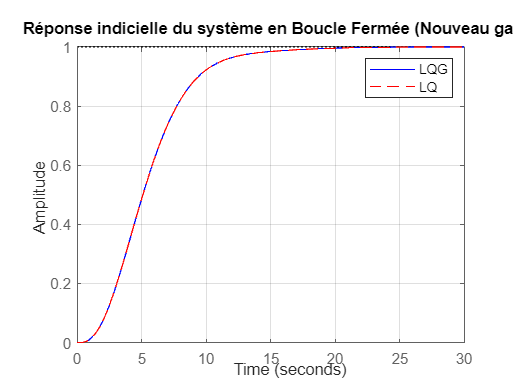

fprintf("Marge de phase 'LQ' : Pm = %.4f deg à %.4f rad/min\n", SLQ.PhaseMargin, SLQ.PMFrequency);

disp("======================================================================")
%Diagramme du bode de la fonction de sensibilité
figure
bode(sys_s, 'b', sys_s_LQ, 'r--')

grid on
title("Diagramme du bode de la fonction de sensibilité (Nouveau gamma)")

Sbf_LQG = struct with fields:
         RiseTime: 7.1487
    TransientTime: 11.0903
     SettlingTime: 11.0903
      SettlingMin: 0.9042
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 32.9853


legend("LQG", "LQ")

Sbf_LQ = struct with fields:
         RiseTime: 7.1487
    TransientTime: 11.0903
     SettlingTime: 11.0903
      SettlingMin: 0.9042
      SettlingMax: 0.9999
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9999
         PeakTime: 32.9853



% Calcul de la marge de module 

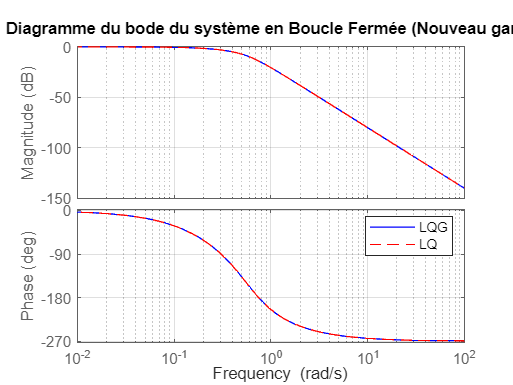

MmLQG = 1/max(bode(sys_s));
MmLQ = 1/max(bode(sys_s_LQ));
disp("===== détermination des marges de Module =====");
fprintf("Marge du modile du Système LQG :\n");
fprintf('Marge de Module :Mm (LQG) =  %.4f', MmLQG);


fprintf("Marge du modile du Système LQ :\n");
fprintf('Marge de Module :Mm (LQ) =  %.2f \n', MmLQ);

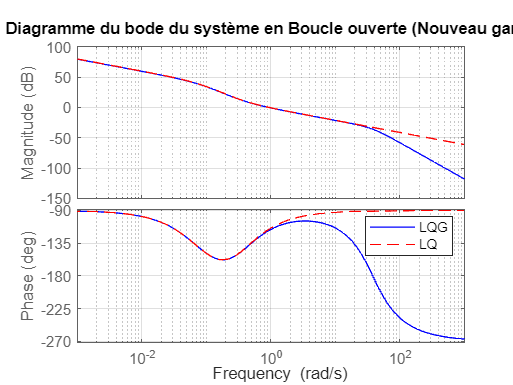


% Vérification des contraintes avec des gains trouvés
disp("===== VÉRIFICATION DES CONTRAINTES AVEC LES GAINS TROUVÉS =====");

fprintf("\n--- CONTRAINTE Mm > 0.95 ---\n");
if MmLQG > 0.9500

fprintf("Système LQG : %.4f > 0.95 => ✓ CONTRAINTE RESPECTÉE \n", MmLQG);
else

    fprintf("Système LQG : %.4f < 0.95 => ✗ CONTRAINTE NON RESPECTÉE", MmLQG);
end

if MmLQG > 0.9500
fprintf("Système LQ : %.4f > 0.95 => ✓ CONTRAINTE RESPECTÉE \n", MmLQ);
else
    fprintf("Système LQ : %.4f < 0.95 => ✗ CONTRAINTE NON RESPECTÉE", MmLQ);

===== détermination des marges de gain et de phase =====


end


Système LQG :


fprintf("\n--- CONTRAINTE Mm > 0.95 ---\n");

Marge de gain 'LQG' : Gm = 35.8895 dB à 37.9144 rad/min


% Pour le système LQG

Marge de phase 'LQG' : Pm = 62.4402 deg à 0.9288 rad/min


if MmLQG > 0.9500
fprintf("Système LQG : %.4f > 0.95 => ✓ CONTRAINTE RESPECTÉE \n", MmLQG);


Système LQ :


else

Marge de gain 'LQ' : Gm =  dB à  rad/min


    fprintf("Système LQG : %.4f < 0.95 => ✗ CONTRAINTE NON RESPECTÉE", MmLQG);

Marge de phase 'LQ' : Pm = 64.4443 deg à 0.9436 rad/min


end
% Pour le système LQ

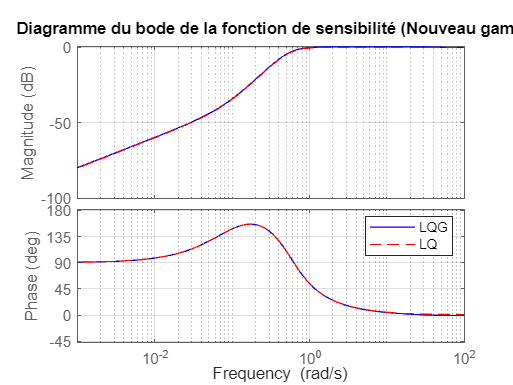

if MmLQ > 0.9500
fprintf("Système LQ : %.4f > 0.95 => ✓ CONTRAINTE RESPECTÉE \n", MmLQ);
else
    fprintf("Système LQ : %.4f < 0.95 => ✗ CONTRAINTE NON RESPECTÉE", MmLQ);
end
%==========================================================================

fprintf("\n--- CONTRAINTE MG > 35 dB ---\n");

% Pour le système LQG
if isempty(GmLQG_dB) || GmLQG_dB > 35 || isnan(GmLQG_dB)
    fprintf("Système LQG : %.4f dB > 35 dB => ✓ CONTRAINTE RESPECTÉE \n", GmLQG_dB);

===== détermination des marges de Module =====


else

Marge du modile du Système LQG :


    fprintf("Système LQG : %.4f dB < 35 dB => ✗ CONTRAINTE NON RESPECTÉE \n", GmLQG_dB);

Marge de Module :Mm (LQG) =  0.9682

end


Marge du modile du Système LQ :


% Pour le système LQ

Marge de Module :Mm (LQ) =  1.00 


if isempty(GmLQ_dB) || GmLQ_dB > 35 || isnan(GmLQ_dB)
    fprintf("Système LQ : %.4f dB > 35 dB => ✓ CONTRAINTE RESPECTÉE \n", GmLQ_dB);
else

===== VÉRIFICATION DES CONTRAINTES AVEC LES GAINS TROUVÉS =====


    fprintf("Système LQ : %.4f dB < 35 dB => ✗ CONTRAINTE NON RESPECTÉE \n", GmLQ_dB);
end


--- CONTRAINTE Mm > 0.95 ---



%==========================================================================
fprintf("\n--- CONTRAINTE Mφ > 60° ---\n");

% Pour le système LQG
if isempty(SLQG.PhaseMargin) || SLQG.PhaseMargin > 60 || isnan(SLQG.PhaseMargin)

Système LQG : 0.9682 > 0.95 => ✓ CONTRAINTE RESPECTÉE 


    fprintf("Système LQG : %.4f ° > 60° => ✓ CONTRAINTE RESPECTÉE \n", SLQG.PhaseMargin);
else
    fprintf("Système LQG : %.4f ° < 60° => ✗ CONTRAINTE NON RESPECTÉE \n", SLQG.PhaseMargin);
end

% Pour le système LQ

Système LQ : 1.0000 > 0.95 => ✓ CONTRAINTE RESPECTÉE 


if isempty(SLQ.PhaseMargin) || SLQ.PhaseMargin > 60 || isnan(SLQ.PhaseMargin)


--- CONTRAINTE Mm > 0.95 ---


    fprintf("Système LQ : %.4f ° > 60° => ✓ CONTRAINTE RESPECTÉE \n", SLQ.PhaseMargin);
else
    fprintf("Système LQ : %.4f ° < 60° => ✗ CONTRAINTE NON RESPECTÉE \n", SLQ.PhaseMargin);
end



Système LQG : 0.9682 > 0.95 => ✓ CONTRAINTE RESPECTÉE 


Système LQ : 1.0000 > 0.95 => ✓ CONTRAINTE RESPECTÉE 



--- CONTRAINTE MG > 35 dB ---


Système LQG : 35.8895 dB > 35 dB => ✓ CONTRAINTE RESPECTÉE 


Système LQ :  dB > 35 dB => ✓ CONTRAINTE RESPECTÉE 



--- CONTRAINTE Mφ > 60° ---


Système LQG : 62.4402 ° > 60° => ✓ CONTRAINTE RESPECTÉE 


Système LQ : 64.4443 ° > 60° => ✓ CONTRAINTE RESPECTÉE 


## Conclusion générale

Nous avons conçu une loi de commande robuste pour la régulation thermique d’une salle blanche. Après modélisation et analyse du système, un observateur de Kalman et une commande LQ avec intégrateur ont été développés, puis combinés en une structure LQG. L’étude a montré les limites de robustesse du LQG et l’intérêt de la procédure LTR, qui permet de retrouver les performances du retour d’état idéal tout en conservant un schéma réaliste basé sur un observateur. Cela illustre concrètement l’apport des méthodes de commande optimale et robuste pour des systèmes thermiques soumis à incertitudes et perturbations.